# Classical Margins

open loop transfer function


$$G(s) = \frac{0.38(s^2+0.1s+0.55)}{s(s+1)(s^2+0.06s+0.5)}$$


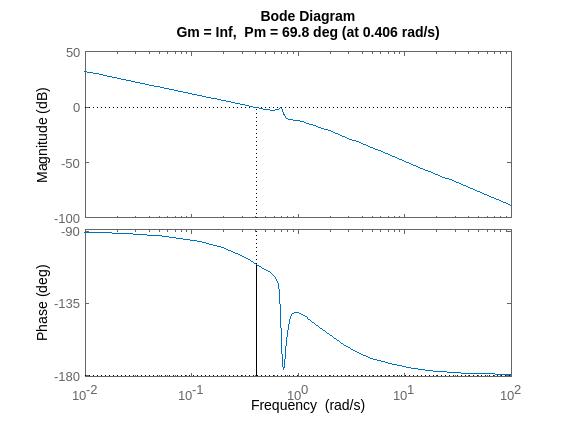

% Define the transfer function
s = tf('s');
G = 0.38*(s^2+0.1*s+0.55)/(s*(s+1)*(s^2+0.06*s+0.5));

% Get classical gain and phase margin
margin(G)

Addtional gain by itself doesn't result in instability

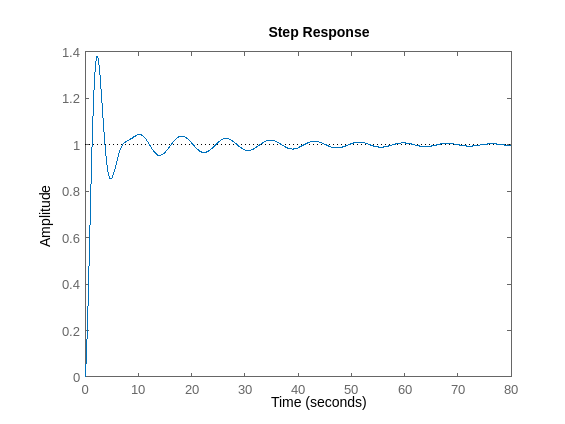

addgain = 15; % 15 dB of extra gain
step(feedback(G*10^(addgain/20),1))

Addtional phase by itself (less than margin) doesn't result in instability

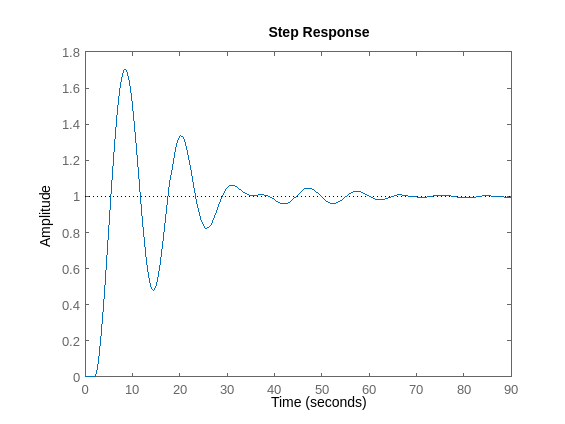

adddelay = 2; % 2 seconds of addtional delay
step(feedback(G*exp(-s*adddelay),1))

Small increase in **both** gain and pahse result in instability

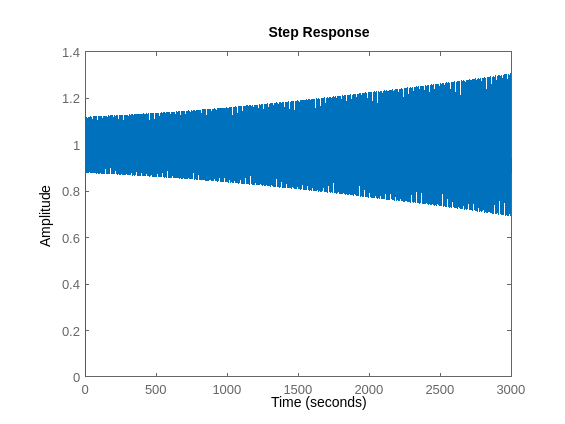

addgain = 3; % 3 dB of extra gain
adddelay = 0.2; % 0.2 seconds of addtional delay
step(feedback(G * 10^(addgain/20)*exp(-s*adddelay),1))

Disk margin accounts for simultaneous gain and pahse pertubations

DM = diskmargin(G)

DM = struct with fields:
           GainMargin: [0.7379 1.3552]
          PhaseMargin: [-17.1526 17.1526]
           DiskMargin: 0.3016
           LowerBound: 0.3016
           UpperBound: 0.3016
            Frequency: 0.7137
    WorstPerturbation: [1×1 ss]


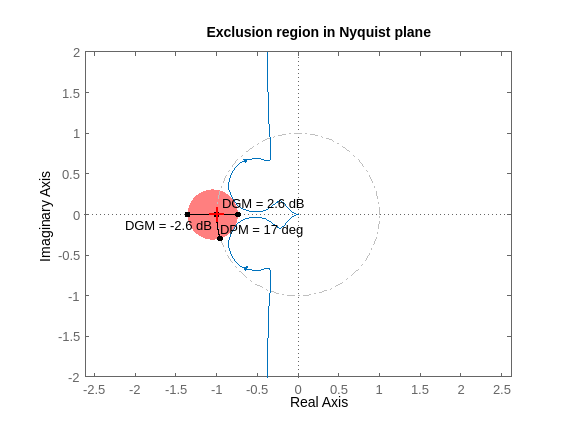

clf, nyquist(G), hold all;
xlim([-2 2])
ylim([-2 2])
diskmarginplot(DM.GainMargin,'nyquist')